# **How the Fly Gets Its Neck**

## James Boedicker, Justin Bois, Hernan G. Garcia and Rob Phillips

How does an embryo decide where along its body to grow legs? How can it tell its head from its tail? Cells combine the information encoded in their DNA with cues from their neighboring cells and the environment in order to make decisions. In the context of embryonic development, these decisions are related to determining where along the body cells will differentiate, proliferate and ultimately become morphological structures such as legs or wings or any other tissue type of a multicellular organism.

Here, we will explore how cells within a fruit fly read out a signal in order to make life-changing decisions about where the "neck"' of the fly will be formed. We will propose a simple model for this decision and calculate the predictions the model makes for flies whose developmental program has been genetically altered. We will then test those predictions experimentally by imaging these genetically-modified flies and analyzing the results using Matlab and find some surprises!

## The development of the fruit fly

The fruit fly *Drosophila melanogaster *begins its life as an egg of about 500 $\mu$m in length and a radius of about $100~\mu\mbox{m}$. Throughout the first three hours of its development, the initial nucleus undergoes multiple rounds of division resulting in approximately 6000 nuclei located on the periphery of the embryo. This process is shown diagrammatically in Figure 1A while an images of a real embryo developing taken using fluorescence two-photon microscopy is presented in Figure 2A.

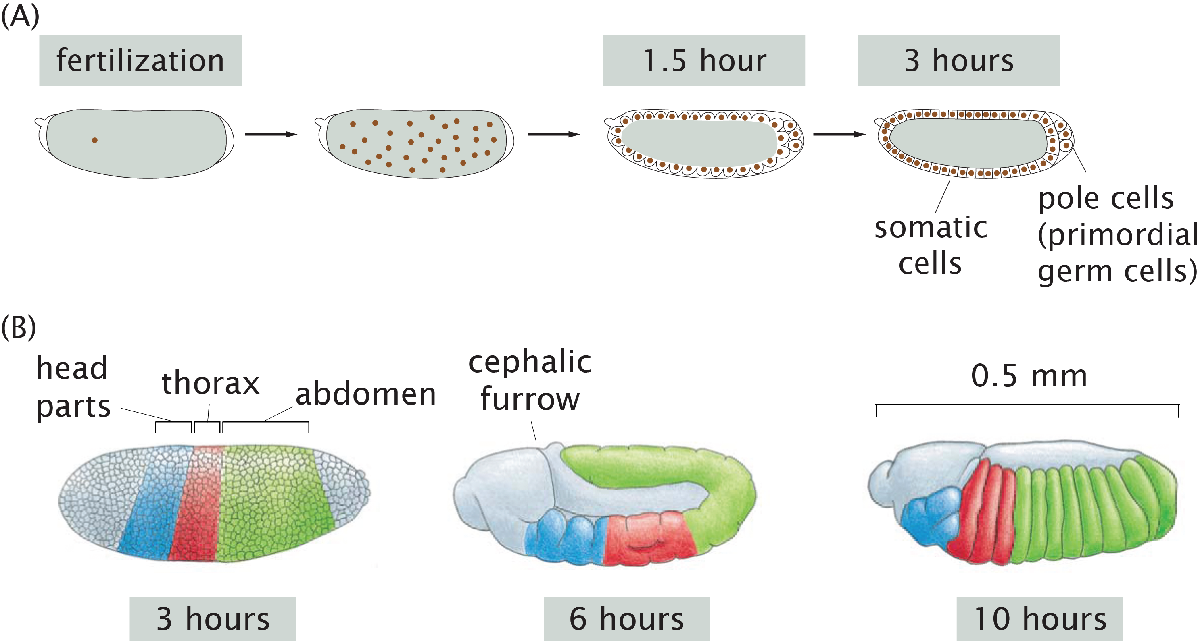

**Figure 1: Schematic of the development of the fruit fly *****Drosophila melanogaster*****.** (A) The fly begins its life as an egg with a single nucleus. By three hours into its development, this nucleus has gone through multiple rounds of division resulting in 6000 cells located all around the periphery of the embryo. (B) At this time cells already express various combinations of gene products determining their ultimate developmental fate. 

As we see from the images in Figure 2A, throughout the early development of the fruit fly, all nuclei look exactly the same. Yet, a genetic program has already taken place during these initial hours that has determine the ultimate developmental fate of each one of its cells. In Figure 1B we see how different cells express various combinations of gene products which specify which part of the adult fly they will become as morphology starts to emerge in the embryo during a process called gastrulation. One such morphological decision is the appearance of the cephalic furrow as seen in Figure 2B. This cephalic furrow appears at about 33.7% embryo length and separates the head from the thorax.

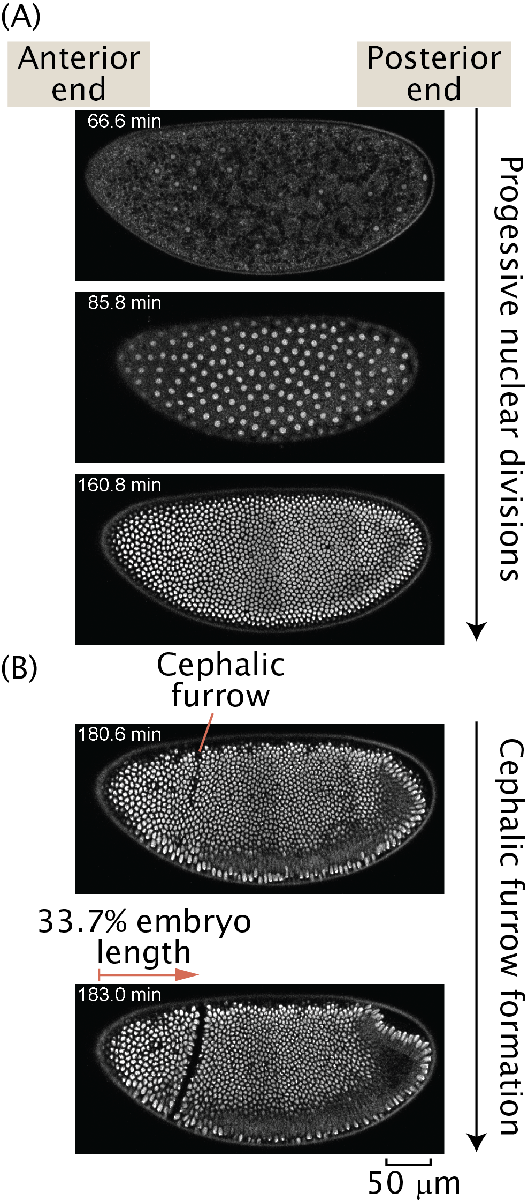

**Figure 2: The early development of the fruit fly using fluorescence microscopy.** Two-photon microscopy movie of a fruit fly embryo whose nuclei are fluorescently labeled. Time stamps indicate the approximate time since fertilization. (A) As time since fertilization progresses (shown in each frame) the number of nuclei increases. By three hours into the development, 6000 nuclei can be observed near the surface of the embryo. (B) At this point, massive morphological changes occur throughout the embryo. One of these changes is the emergence of the cephalic furrow at about 33.7% embryo length. This furrow is a tissue fold that will determine the separation between the head and the thorax of the embryo.

How does the embryo figure out where to place the cephalic furrow? In this exercise we will explore a simple model that proposes a mechanism for the placement of morphological features along the embryo axis by testing its predictions experimentally.

## The French flag model

A very popular model to explain how embryos can measure the position where morphological features will appear is called "The French flag model" and was proposed by Wolpert (Wolpert 1969). The basic idea of this model is shown in Figure 3. Here, a gradient of a molecule called a "morphogen" is present along the anterior-posterior axis of the embryo. Cells determine where they are along the embryo by measuring the local morphogen concentration. In the example of the figure the cells that see a concentration above "threshold 1" carry out a specific developmental program indicated with blue. Cells that see a concentration between "threshold 1" and "threshold 2" adopt the white cellular fate while those that see a concentration below "threshold 2" carry out the red developmental program.

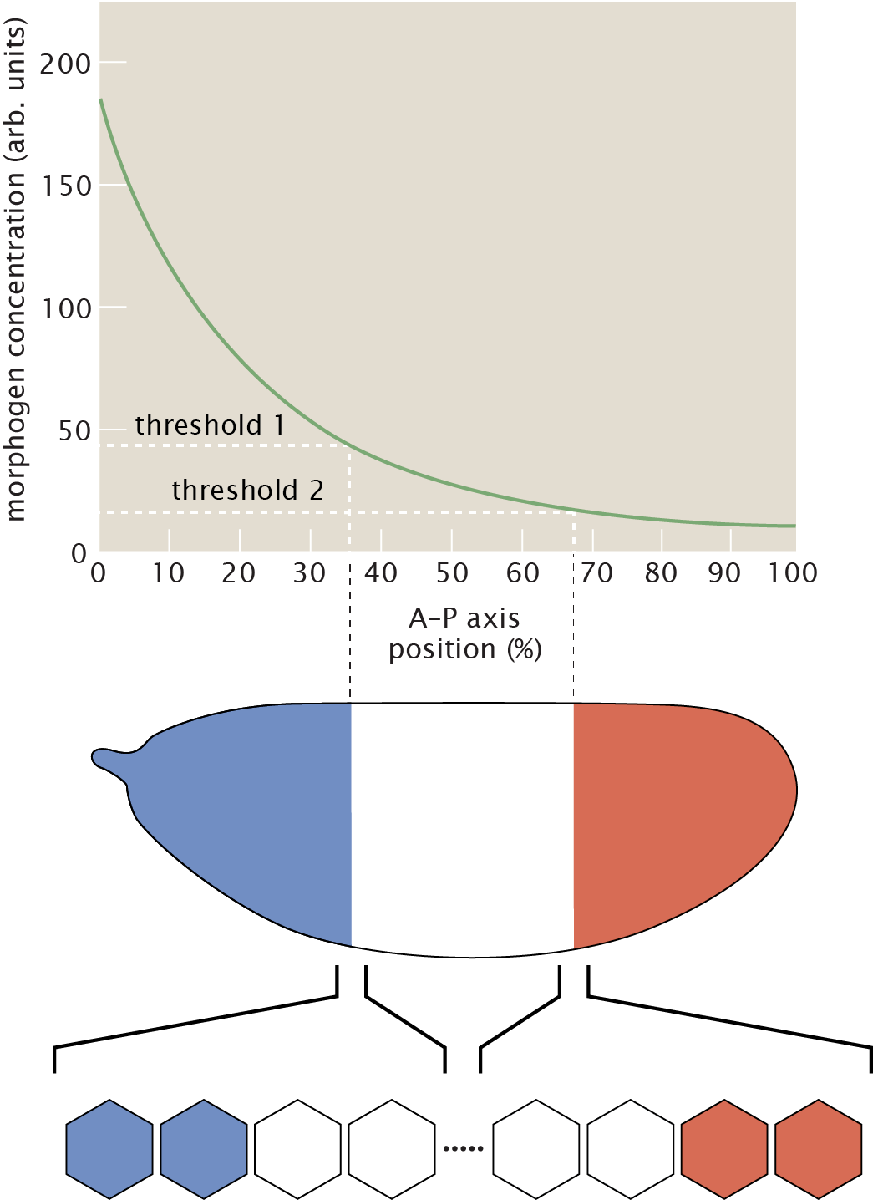

**Figure 3: French flag model of positional information. **A morphogen gradient is present along the long (anterior–posterior) axis of the embryo. When the concentration of the morphogen exceeds a first threshold, cells adopt the "blue" developmental fate, while when they are below the first threshold but above a second threshold, they adopt the "white" fate.

A classic morphogen in the fly is the activator Bicoid. This protein is produced at the anterior end of the embryo and diffuses throughout its whole length (Driever and Nusslein-Volhard 1988). The result is an exponential gradient, as shown in Figure 3, which can be mathematically described as


$$[Bcd](x) = [Bcd]_0 e^{-x/\lambda}.$$


Here $[Bcd]_0$ is the Bicoid concentration at the source, $x$ is the position along the embryo's axis, and $\lambda$ is the decay length of the exponential gradient. Bicoid is one of the main determinants of positions along the anterior-posterior axis of the embryo. Now, let's assume that it marks the position of the cephalic furrow at $x_0$. The corresponding Bicoid concentration at that position is


$$[Bcd] (x = x_0) = [Bcd]_0 e^{-x_0/\lambda}.$$


Let's imagine that we rescale the gradient by a factor $D$. This can be done, as we will see below, by changing the number of copies of the *bicoid* gene in the *Drosophila*. The resulting Bicoid profile would then be


$$[Bcd](x,D) = D [Bcd]_0 e^{-x/\lambda}.$$


The feature that appeared at position $x_0$ due to the Bicoid concentration $[Bcd] (x_0)$ at that location will now be shifted to a new position $x_{new}$. In order to calculate this new position we equate the two equations


$$[Bcd](x_0,D=1) = [Bcd](x_{new},D)$$


which leads to


$$    [Bcd]_0 e^{-x_0/\lambda} = D [Bcd]_0 e^{-x_{new}/\lambda}
$$


resulting in


$$x_{new} = D \ln(D) + x_0.$$
    

This equation tells us that the new position of the feature should scale linearly with $\ln(D)$. As a first exercise, we will plot this prediction using Matlab. Specifically, we want to plot the new position of the cephalic furrow $x_{new}$ as a function of the *bicoid* dosage $D$. As with any plot, our goal is to find a set of x and y values that can be used to generate the graph. One stragtegy is to define a vector of possible $D$ values (the x-values in our plot) by inputting them manually such that

D = [0.3,0.4,0.5];

However, it is clear that this is not a good strategy if you want to generate hundreds of different values for $D$! Instead, we can use the function `linspace`, which generates 100 equally spaced values between the two input arguments to the function

D=linspace(0.3,5);  %Create 100 equally spaced points between 0.3 and 5
D

D =     0.3000    0.3475    0.3949    0.4424    0.4899    0.5374    0.5848    0.6323    0.6798    0.7273    0.7747    0.8222    0.8697    0.9172    0.9646    1.0121    1.0596    1.1071    1.1545    1.2020    1.2495    1.2970    1.3444    1.3919    1.4394    1.4869    1.5343    1.5818    1.6293    1.6768    1.7242    1.7717    1.8192    1.8667    1.9141    1.9616    2.0091    2.0566    2.1040    2.1515    2.1990    2.2465    2.2939    2.3414    2.3889    2.4364    2.4838    2.5313    2.5788    2.6263


Next, in order to generate our prediciton, we need to commit to values of $\lambda$ and $x_o$. After Liu *et al., *2013, these model parameters are

xCF=0.337;           %Fraction of the embryo at which the cephalic furrow shows up in the wild-type case
lambda=0.191;        %Bicoid decay length in units of fraction of embryo length

We are now ready to calculate the set of new cephalic furrow positions corresponding to the dosage values in `D`.

xNew=xCF+lambda*log(D);

Finally, we can plot our prediciton. Note that the function `plot` takes as its input arguments a set of x- and y-values that define points on the graph. If we give `plot `an extra argument `'-'` it will connect those points using lines. Finally, `'-r'` makes that line red.

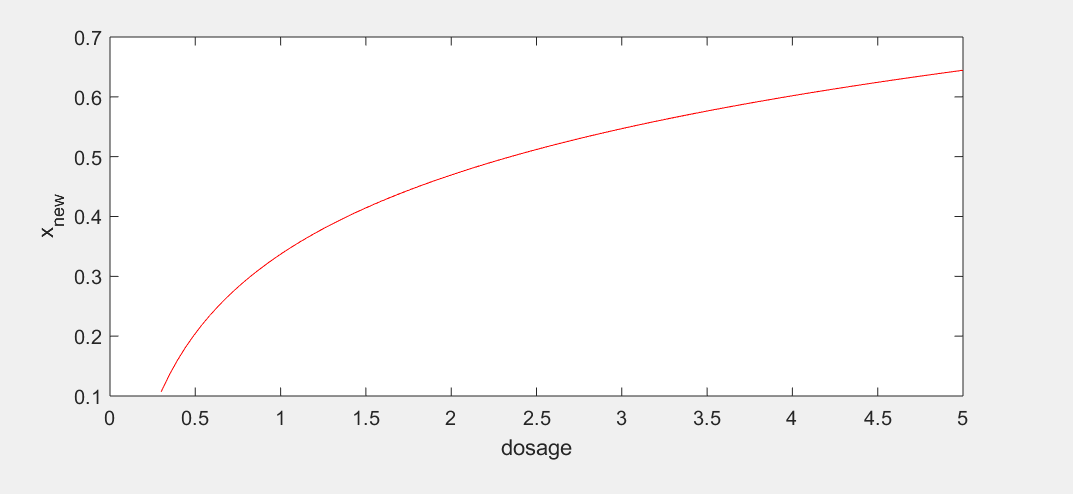

plot(D,xNew,'-r')
xlabel('dosage')
ylabel('x_{new}')

where we have also defined axis labels. Note that our prediction states that the new cephalic furrow position depends on $\ln(D)$. As a result, it could be informative to plot our prediction on a linear-log plot

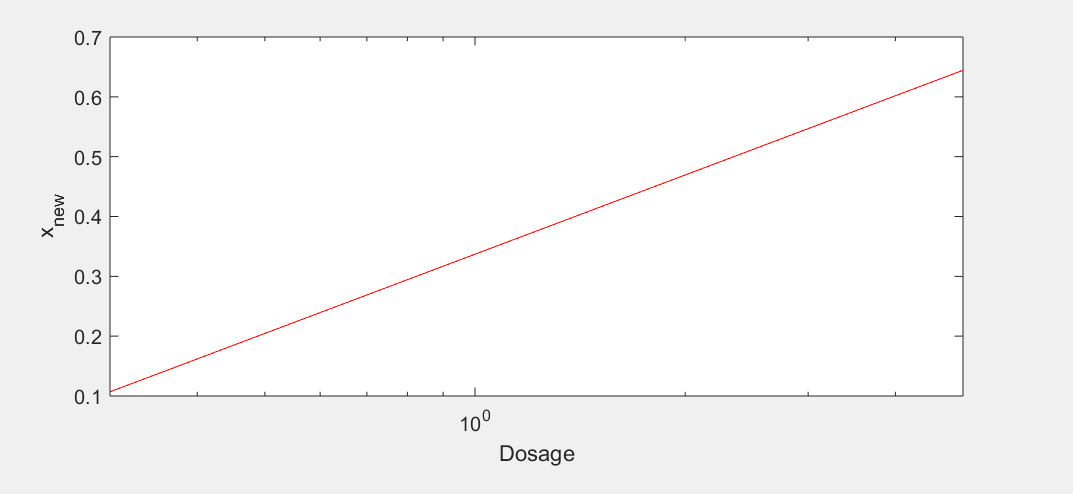

semilogx(D,xNew,'-r')
xlabel('Dosage')
ylabel('x_{new}')

In order to test this prediction, we will have to change the dosage of Bicoid in the embryo and measure the position of the cephalic furrow using image analysis in Matlab. In the next section we discuss how to engineer this mutant fly, something that has been going on behind the scenes for the last few days.

## Creating flies with different Bicoid dosages

There are multiple ways of varying the amount of Bicoid in an embryo. The easiest way it to reduce the Bicoid amount by a factor of two. Remember that flies are diploid, which means that they carry two copies of each chromosome and, as a result, they carry two copies of the *bicoid* gene. Halving the Bicoid dosage can then be done by having one copy of the chromosome with a functional *bicoid *gene and one copy with a mutant, non-functional gene. In this section we will walk you through the fly crosses that took place a few days before this experiment in order to create these mutant flies.

Before we begin, let's look at some nomenclature. Female virgin flies are denoted by the symbol  , while males are represented by . A wild-type chromosome is denoted by the symbol $+$, while a mutant *bicoid* gene is denoted by the symbol $bcd$. Since we're dealing with a diploid organism we need to indicate what each chromosome is. For example, two wild-type chromosomes are indicated by ${+ \over +}$. If we have a mutant *bicoid* gene in one chromosome and wild-type one in another this is indicated by ${bcd \over +}$.

Bicoid is a protein that is provided by the mother. This means that if we do the mating

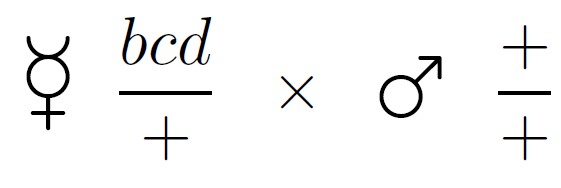

the embryos coming out of this cross will have only half the amount of Bicoid protein they would have had if their mothers were ${+ \over +}$. The question is then, how do we create flies with the genotype $\frac{bcd}{+}$? In order to create these flies we had to do the previous mating

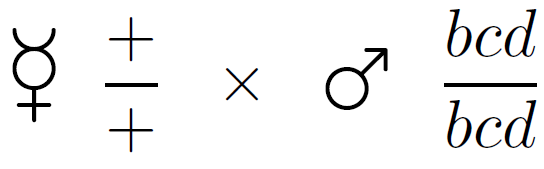

so all offspring are $bcd/+$. We can then pick the females from this cross and use them as the mothers of our experiment. To get the wild-type Bicoid dosage we will just use wild-type flies. Similatly, extra copies of the *bicoid* gene can be introduced in the genome in order to increase the Bicoid concentration.

## Experimental protocol

We will take images of fly lines with different Bicoid dosages using light microscopy. The trick will be getting the embryos at the right developmental time point so that the cephalic furrow is easy to image. Our images will look similar to those shown in Figure 4. We will then use Matlab to analyze these images and determine the position of the cephalic furrow for the different Bicoid dosages in order to test the prediction of the French flag model.

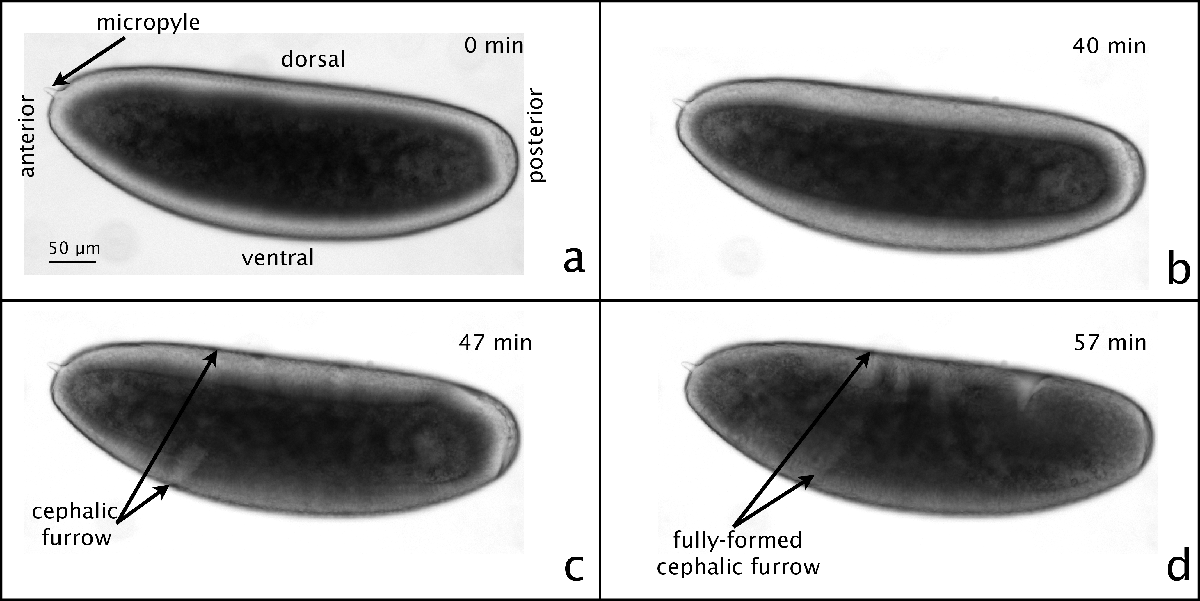

**Figure 4: Images of a wild type *****Drosophila***** embryo acquired in bright field.** (a) The embryo immediately after completing 13 rounds of nuclear division.  Note that the periphery of the embryo, where the nuclei are, is lighter in color. The anterior of the embryo is marked by the small protrusion called the micropyle. The dorsal side of the embryo has less curvature than the ventral side. (b) The embryo immediately after cellularization. The formation of the cephalic furrow will occur within minutes. (c) Approximately one minute after cephalic furrow ingression begins. The furrow is clearly visible. The arrows mark the position of the furrow on the dorsal and ventral sides of the embryo. This is the best time to see the cephalic furrow, as the cells at the periphery are still light in color. (d) A fully formed cephalic furrow.  The furrow has moved slightly from its position at its initial ingression, and is more difficult to see.

To measure the cephalic furrow, we need to isolate live embryos at the right stage of development, mount, and image them. There are two crucial points here.  First, we need to make sure the embryos are at the correct stage of development for formation of the cephalic furrow. Second, we need to remove the *chorion*, the protective shell of the embryo, before imaging. The chorion is reflective, and will greatly compromise image quality if not removed. Below, we describe the protocol we will use in lab. While it differs in some ways from our protocol, you may find it useful to watch the video description of acquisition and imaging of eggs found in Figard and Sokac, 2011.

We will provide you with slides where the embryos have already been mounted. Find a few embryos and take a time lapse movie with a frame every 30s to 1min. From the time lapse movies, we will find the frame where the cephalic furrow first forms and determine its position. Remember that you can use Figure 4 as a guide.

## Finding the cephalic furrow position

We begin by loading a frame from the movies we obtained. This frame correspnds to the first time point where the cephalic furrow is visible for the wild-type case of $D=1$.

Embryo=imread('1xBcd.tif');

Here, we used the function `imread` in order to load the file `1xBcd.tif` onto the variable `Embryo.` See what happens if you don't use the "`;`" at the end of the line! Remember that images are just matrices. The number encoded in this position of this matrix encodes for the pixel intensity at the corresponding location in the image. Note that this variable is a matrix/image of 359 rows and 853 columns.

size(Embryo)

ans =    359   853


We can display it using the command `imshow`

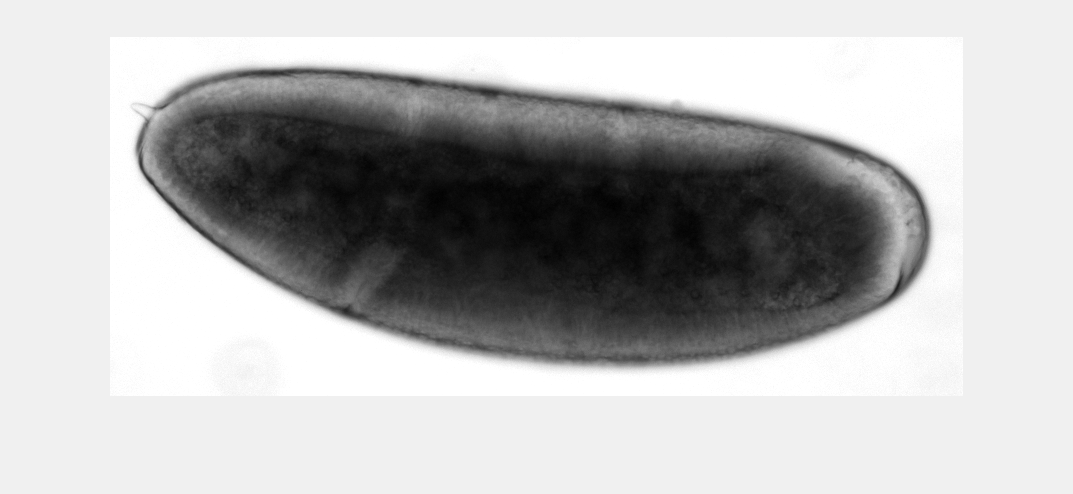

imshow(Embryo)

where the cephalic furrow is clearly visible. There are many ways to define the position of this cephalic furrow relative to the length of the embryo. In fact, there is no agreement in measurement strategy between the labs that work on this subject. We are going to measure the position of the furrow along the ventral (curved) side of the embryo. Further, we'll use a manual approach to find this position: we will click on it.

We will click along the ventral side in order to draw its contour and measure the total length of the embryo. We will then use this same strategy to measure the distance from the anterior end to the cephalic furrow. To make this possible, we will use the function `ginput` and save the results in the variable `Clicks`. This function saves the positions where you clicked in the current image. Click along the embryo, starting from the anterior end along the ventral side all the way to the posterior end to draw an outline of the embryo. Note which click number corresponds to the cephalic furrow. When you're done clicking, press enter.

**NOTE: **Every time you re-run this Live Script, the `ginput` command will run again and your variable `Clicks` will be overwritten. So, after you run the next line for the first time, make sure to comment it out with a `%`. If you want to rerun this script from scratch, just remove the `%`.

%Clicks=ginput;

When I did it, my 10th click corresponded to the cephalic furrow. I'll save this information in `CFClick`.

CFClick=10;

Let's see how good of a job we did at tracing the contour of the embryo by overlaying the image with a plot of the clicks. First, extract the x and y values from `Clicks`. The first column of this matrix corresponds to all x-values while the second column contains all y-values.

xClicks=Clicks(:,1);        %All rows in the first column of Clicks
yClicks=Clicks(:,2);        %All rows in the second column of Clicks

Now, we show the image once again. In addition, we use the command `hold on` so that we can overlay a plot on top of it. Remember to write `hold off `when using this command. 

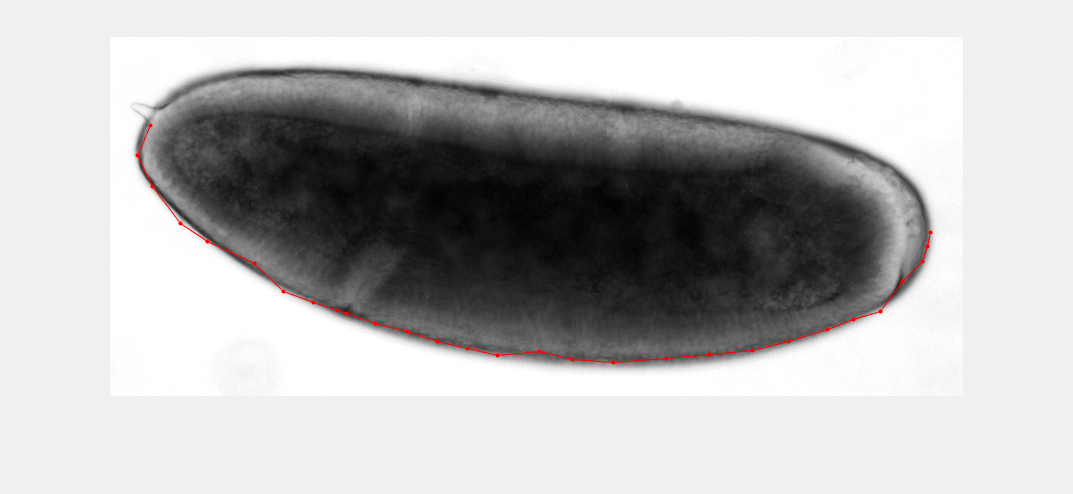

imshow(Embryo)
hold on
plot(xClicks,yClicks,'.-r')
hold off

Note that the option `'.-r'` for `plot` returned red dots connected by lines.

We now calculate the total length of the anterior-posterior axis by summing over the length of each segment determined by our clicks. The length of a segment between points 1 and 2 is given by $\sqrt{(x_2-x_1)^2 + (y_2-y_1)^2}$. Basically, we want to do this for all segments and then add them up to get the total length. First, we create "Delta" vectors that have, for example, `DeltaX=[x2-x1,x3-x2,...]. `This can be done using the `diff `function.

DeltaX=diff(xClicks);
DeltaY=diff(yClicks);

Second, we calculate the square of each Delta element. Note that we need to raise to the power of 2 in an element-wise fashion by using the "`.`" operator.

DeltaX2=DeltaX.^2;
DeltaY2=DeltaY.^2;

Third, we add `DeltaX2` and `DeltaY2.`

SquareLengths=DeltaX2+DeltaY2;

Finally, we take the the square root and obtain a vector of lengths fo each segment.

Lengths=sqrt(SquareLengths);

We can now calculate the total axis length by summing over all elements of `Lengths`

LengthEmbryo=sum(Lengths);

and compute the length until the cephalic furrow by adding Lengths from `1` to `CFClick-1`

LengthCF=sum(Lengths(1:CFClick-1));

Resulting in a position of the cephalic furrow measured relative to the length of the anterior-posterior axis given by

LengthCF/LengthEmbryo

ans = 0.3216

## Comparing our measurements to the prediction of the French flag model

If you repeat the analysis shown above for embryos with different Bicoid dosages, you will arrive at data such as

DData=[0.5,1,2];
xNewData=[0.25,0.34,0.36];

where `DDdata `corresponds to the dosages used and `xNewData `to the respective measured cephalic furrow positions. Let´s overlay the prediction with our data.

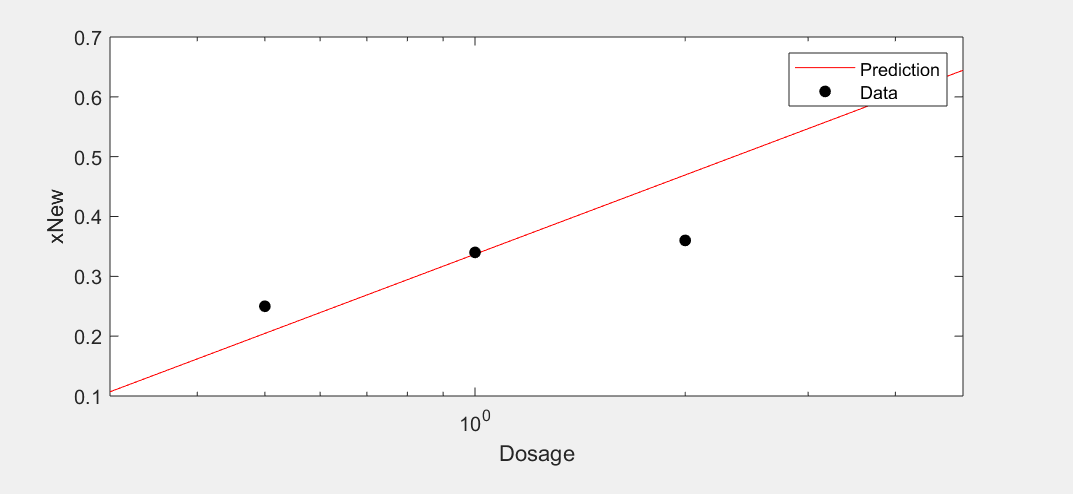

semilogx(D,xNew,'-r')
xlabel('Dosage')
ylabel('xNew')
hold on
plot(DData,xNewData,'.k','MarkerSize',20)
hold off
legend('Prediction','Data')   % Add a plot legend

Clearly, there is a disagreement between our model's prediction and the experimental results. This disagreement could, of course, be related to some systematic error in the experiment. However, researchers have confirmed these measurements repeatedly (Liu *et al.*, 2013). So, it looks like the *qualitative* prediction of the French flag model holds: decreasing the *bicoid* dosage shifts the cephalic furrow anteriorly, while increasing *bicoid* concentration shifts the furrow towards the posterior end of the embryo. However, when we commit to a mathematical model, the *quantitative* prediction of the French flag model does not  corresponds to the experimetnal data. The cephalic furrow moves in the right direction, but it doesn't do so as much as predicted as if there was some sort of "compensation" the fly embryo is capable of doing in order to keep its body plan unaffected in the face of significant changes in its protein levels.

The disagreement between theory and experiment suggests that one of the assumptions utilized to craft our mathematical model migth not be correct. For example, our assumption of Bicoid directly determining the cephalic furrow is certainly not correct, as illustrated in Figure 5. In this figure, we show the gene regulatory network dictating anterior-posterior patterning in the early fly embryo. As shown in the figure, Bicoid lies all the way at the very top of this gene regualtory cascade while the cephalic furrow is so far down that is not even featured. Thus, cells might be using cues from multiple morphogens, not just Bicoid, in order to determine whether they will take part in cephalic furrow formation.

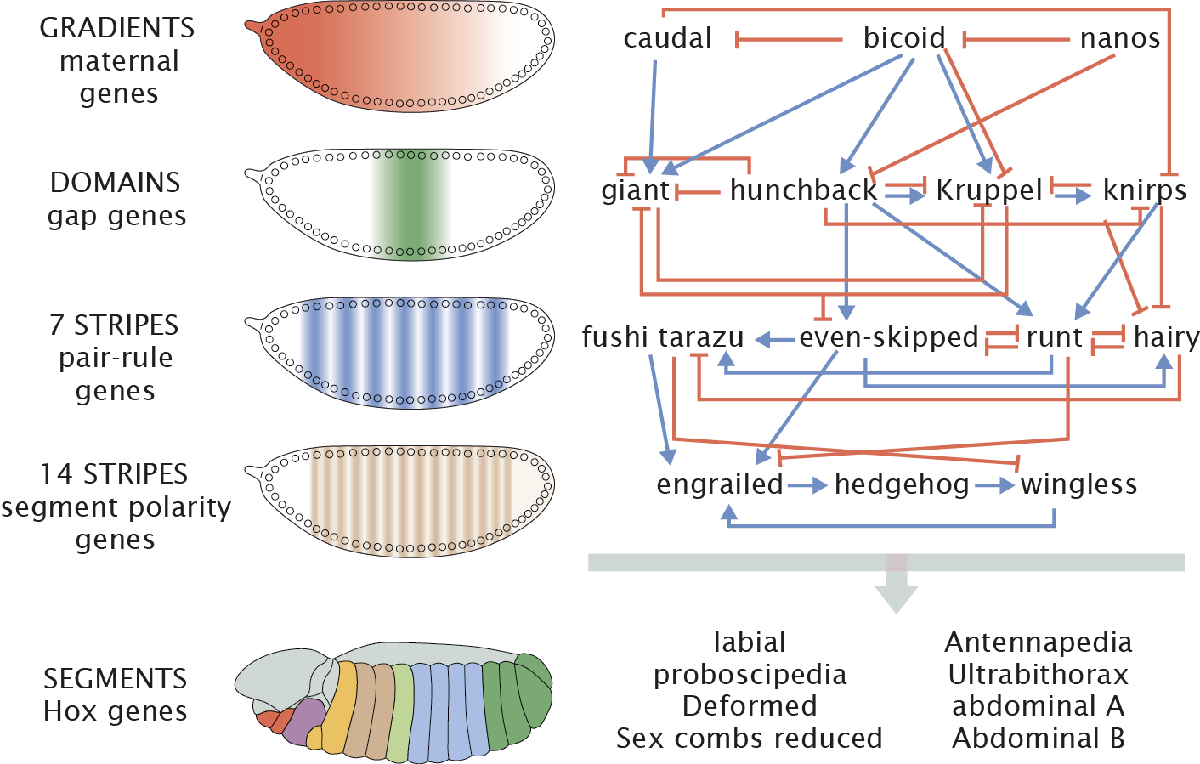

**Figure 5: Gene regulatory network dictating fruit fly development.** The network is organized in a cascade of genes expressed in increasingly sharp spatiotemporal patterns. (Adapted from Carroll *et al.*, 2001 and Jaeger, 2011.)

This view stating that multiple elements of the network dictate the placement of developmental features is supported by the data shown in Figure 6. Here, we show measurements of the Hunchback pattern, which is located directly downstream from Bicoid in the network shown in Figure 5. In Figure 6B we see how, early on in development, the Hunchback boundary moves along the embryo as a result of changes to *bicoid* dosage in a way consistent with the French flag model. At these early times, Bicoid is the only input to Hunchback. However, as development progresses and more input morphogens are produced, the Hunchback boundary position deviates from the prediction.

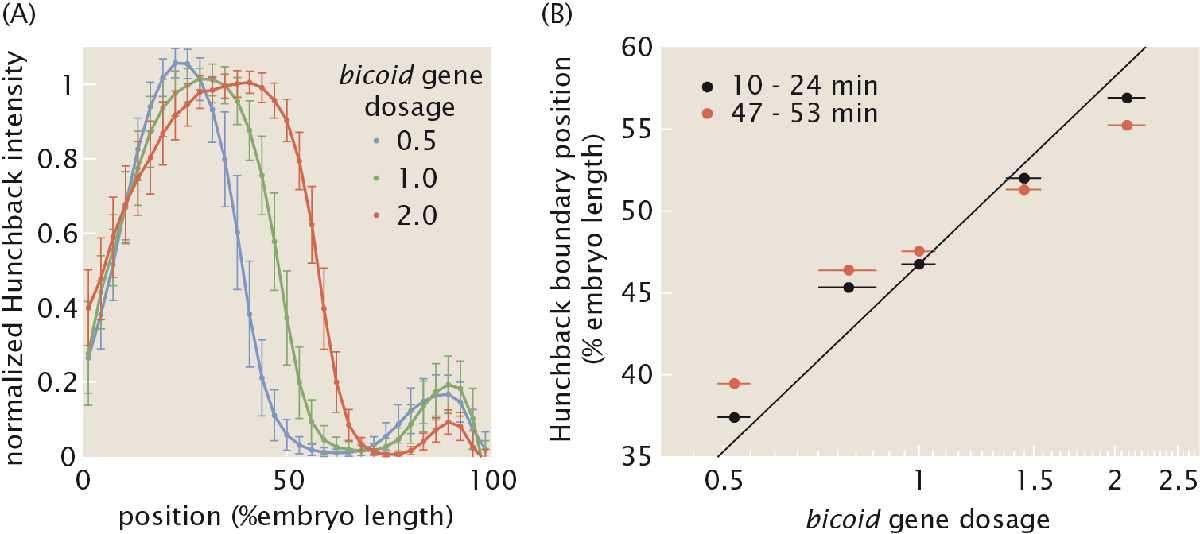

**Figure 6: Dynamic compensation of the Hunchback pattern.** (A) Hunchback protein pattern for different *bicoid* gene dosages. (B) Position of the Hunchback boundary as a function of *bicoid* dosage at different time points in development. (Adapted from Liu *et al.*, 2013.)

This exercise is a stark reminder of the power of committing to a mathematical view of our cartoon models. Without the mathematical expression stemming from the French flag model we would not have been able to discover this "surprise" in how the fly reads out input morphogens in order to determine the position of developmental boundaries. The code we wrote is also an example of how image analysis doesn't have to be fancy or automated: sometimes you just need a quick answer. Interestingly, in the real world, the cephalic furrow is also measured by clicking (Liu *et al.*, 2013)!

## References

Carroll, S.B., Grenier, J.K., and Weatherbee, S.D. (2001). From DNA to diversity: molecular genetics and the evolution of animal design (Malden, Mass.: Blackwell Science).

Driever, W., and Nusslein-Volhard, C. (1988). The bicoid protein determines position in the Drosophila embryo in a concentration-dependent manner. Cell 54, 95-104.

Figard, L., and Sokac, A.M. (2011). Imaging cell shape change in living Drosophila embryos. J Vis Exp.

Jaeger, J. (2011). The gap gene network. Cell Mol Life Sci 68, 243-274.

Liu, F., Morrison, A.H., and Gregor, T. (2013). Dynamic interpretation of maternal inputs by the Drosophila segmentation gene network. Proc Natl Acad Sci U S A 110, 6724-6729.

Wolpert, L. (1969). Positional information and the spatial pattern of cellular differentiation. J Theor Biol 25, 1-47.